By Ethan Harvey

This program runs KMeans on the dataset loaded in by the user. Below the number of footsteps in the dataset is declared.

NumTrainCase = 231+338+346+311

NumTrainCase = 1226

 Below the label is added to each item in the dataset (left or right).

for ind_trnCase = 1:NumTrainCase
    if ind_trnCase <= 231
        Data(ind_trnCase,:)=stepOut(:,ind_trnCase);
        DatLabl(ind_trnCase)=categorical(cellstr('1'));
    elseif ind_trnCase <= (231+338)
        Data(ind_trnCase,:)=stepOut(:,ind_trnCase);
        DatLabl(ind_trnCase)=categorical(cellstr('2'));
    elseif ind_trnCase <= (231+338+346)
        Data(ind_trnCase,:)=stepOut(:,ind_trnCase);
        DatLabl(ind_trnCase)=categorical(cellstr('3'));
    else
        Data(ind_trnCase,:)=stepOut(:,ind_trnCase);
        DatLabl(ind_trnCase)=categorical(cellstr('4'));
    end
end
DatLabl = DatLabl';
DataTable=table(Data);
DatMean = DataTable

DatMean = 1226×1 table
         Data     
    ______________

    [1×397 double]
    [1×397 double]
    [1×397 double]
    [1×397 double]
    [1×397 double]
    [1×397 double]
    [1×397 double]
    [1×397 double]
    [1×397 double]
    [1×397 double]
    [1×397 double]
    [1×397 double]
    [1×397 double]
    [1×397 double]
    [1×397 double]
    [1×397 double]


kMean = zeros(NumTrainCase,1);
DatMean.kMean=kMean;

Next the label is appended to the DatMean table.

DatMean.description=DatLabl;
first_step = DatMean.Data(1,:);
second_step = DatMean.Data(2,:);
third_step = DatMean.Data(3,:);
fourth_step = DatMean.Data(4,:);
fifth_step = DatMean.Data(5,:);
sixth_step = DatMean.Data(6,:);
seventh_step = DatMean.Data(7,:);
eighth_step = DatMean.Data(8,:);

Next a series average and edit is calculated. There is one series edit value for each footstep. The series edit is made up of integers ranging from -10 to 10 and is based off the distance of each footstep from the series average.

series_average = Average(NumTrainCase, DatMean);
series_edit = EditDistance(NumTrainCase, DatMean, series_average);

Then a number of generations are run using a KMean model.

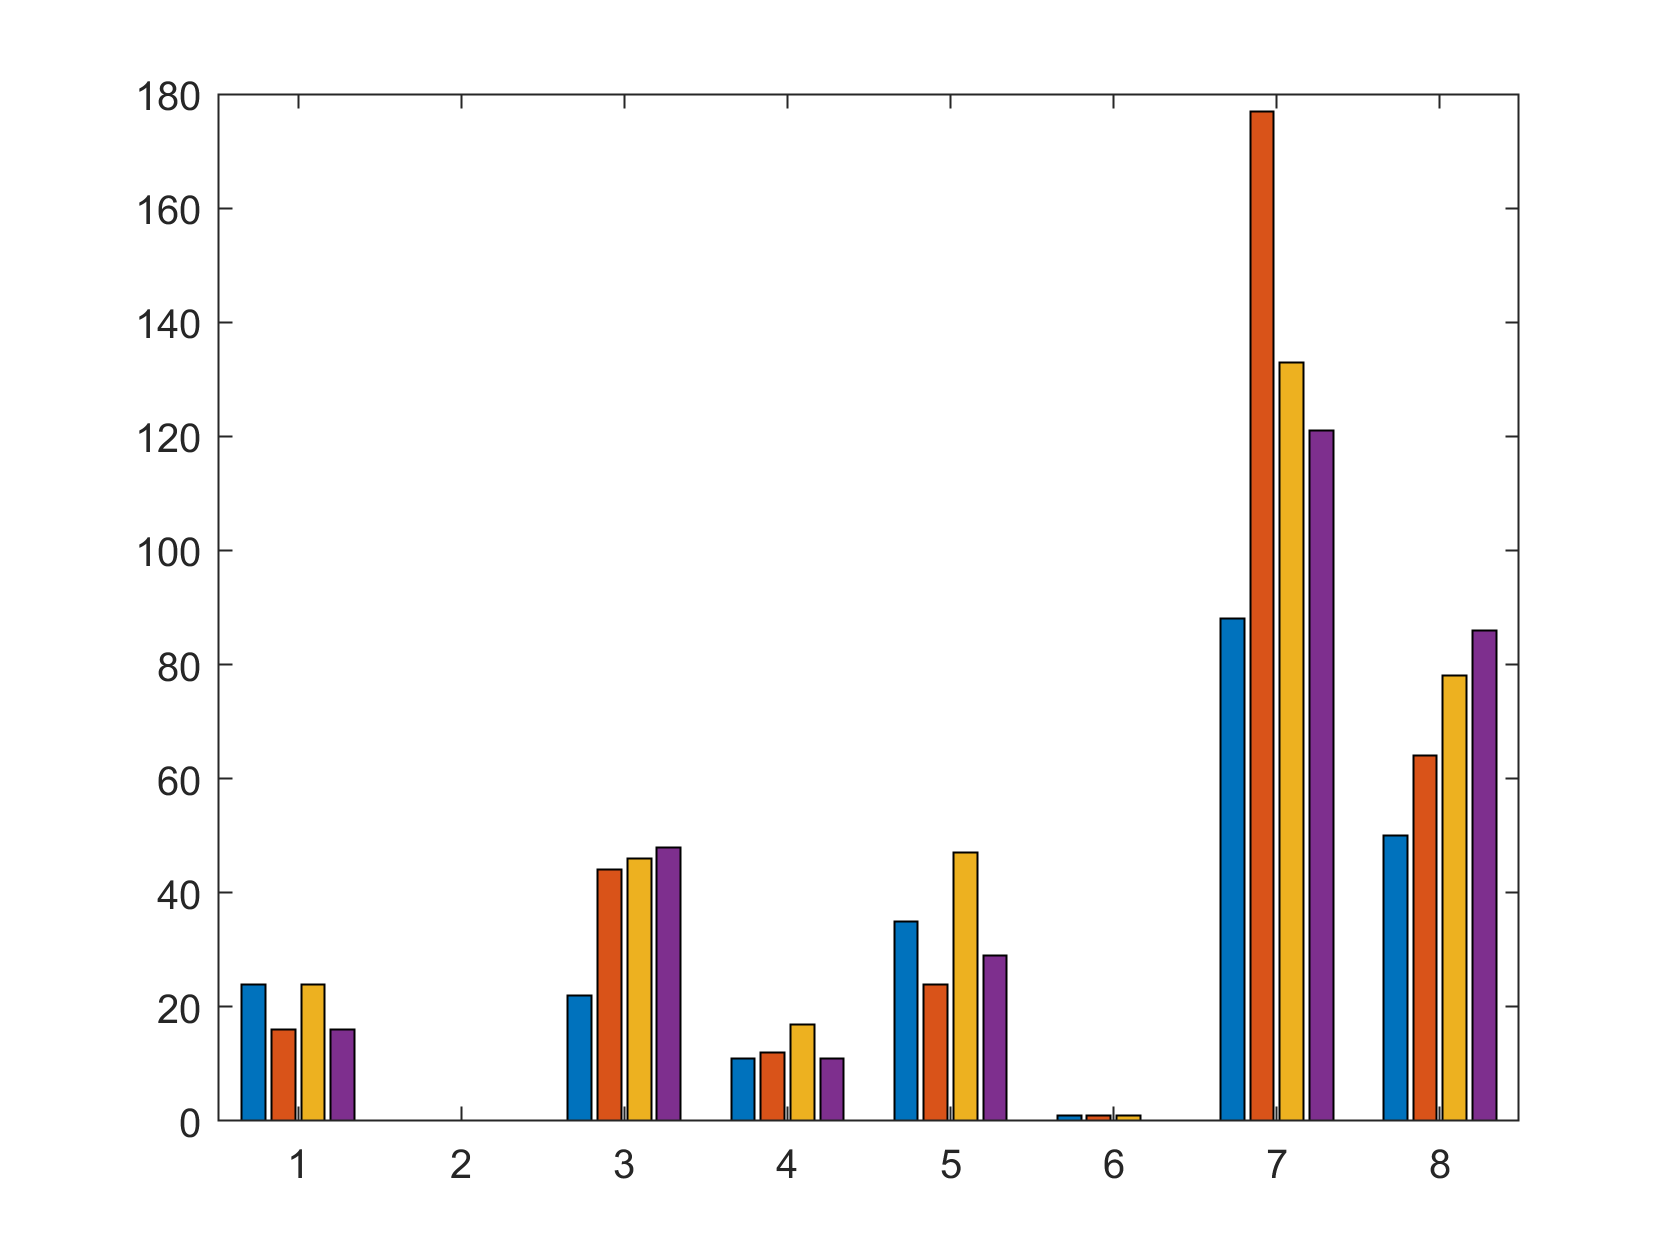

[DatMean, k1, k2, k3, k4, k5, k6, k7, k8] = KMeanFunction(NumTrainCase, DatMean, series_edit, first_step, second_step, third_step, fourth_step, fifth_step, sixth_step, seventh_step, eighth_step);
for i=1:30
    [DatMean, k1, k2, k3, k4, k5, k6, k7, k8] = KMeanFunction(NumTrainCase, DatMean, series_edit, k1, k2, k3, k4, k5, k6, k7, k8);
end
group1_ones = sum(DatMean.kMean==1 & DatMean.description=="1");
group2_ones = sum(DatMean.kMean==1 & DatMean.description=="2");
group3_ones = sum(DatMean.kMean==1 & DatMean.description=="3");
group4_ones = sum(DatMean.kMean==1 & DatMean.description=="4");

group1_twos = sum(DatMean.kMean==2 & DatMean.description=="1");
group2_twos = sum(DatMean.kMean==2 & DatMean.description=="2");
group3_twos = sum(DatMean.kMean==2 & DatMean.description=="3");
group4_twos = sum(DatMean.kMean==2 & DatMean.description=="4");

group1_threes = sum(DatMean.kMean==3 & DatMean.description=="1");
group2_threes = sum(DatMean.kMean==3 & DatMean.description=="2");
group3_threes = sum(DatMean.kMean==3 & DatMean.description=="3");
group4_threes = sum(DatMean.kMean==3 & DatMean.description=="4");

group1_fours = sum(DatMean.kMean==4 & DatMean.description=="1");
group2_fours = sum(DatMean.kMean==4 & DatMean.description=="2");
group3_fours = sum(DatMean.kMean==4 & DatMean.description=="3");
group4_fours = sum(DatMean.kMean==4 & DatMean.description=="4");

group1_fives = sum(DatMean.kMean==5 & DatMean.description=="1");
group2_fives = sum(DatMean.kMean==5 & DatMean.description=="2");
group3_fives = sum(DatMean.kMean==5 & DatMean.description=="3");
group4_fives = sum(DatMean.kMean==5 & DatMean.description=="4");

group1_sixes = sum(DatMean.kMean==6 & DatMean.description=="1");
group2_sixes = sum(DatMean.kMean==6 & DatMean.description=="2");
group3_sixes = sum(DatMean.kMean==6 & DatMean.description=="3");
group4_sixes = sum(DatMean.kMean==6 & DatMean.description=="4");

group1_sevens = sum(DatMean.kMean==7 & DatMean.description=="1");
group2_sevens = sum(DatMean.kMean==7 & DatMean.description=="2");
group3_sevens = sum(DatMean.kMean==7 & DatMean.description=="3");
group4_sevens = sum(DatMean.kMean==7 & DatMean.description=="4");

group1_eights = sum(DatMean.kMean==8 & DatMean.description=="1");
group2_eights = sum(DatMean.kMean==8 & DatMean.description=="2");
group3_eights = sum(DatMean.kMean==8 & DatMean.description=="3");
group4_eights = sum(DatMean.kMean==8 & DatMean.description=="4");
bar([group1_ones,group2_ones,group3_ones,group4_ones; ...
    group1_twos,group2_twos,group3_twos,group4_twos; ...
    group1_threes,group2_threes,group3_threes,group4_threes; ...
    group1_fours,group2_fours,group3_fours,group4_fours; ...
    group1_fives,group2_fives,group3_fives,group4_fives; ...
    group1_sixes,group2_sixes,group3_sixes,group4_sixes; ...
    group1_sevens,group2_sevens,group3_sevens,group4_sevens; ...
    group1_eights,group2_eights,group3_eights,group4_eights]);

    [DatMean, k1, k2, k3, k4, k5, k6, k7, k8] = KMeanFunction(NumTrainCase, DatMean, series_edit, k1, k2, k3, k4, k5, k6, k7, k8);

    group1_ones = sum(DatMean.kMean==1 & DatMean.description=="1");

    group2_ones = sum(DatMean.kMean==1 & DatMean.description=="2");

    group3_ones = sum(DatMean.kMean==1 & DatMean.description=="3");

    group1_twos = sum(DatMean.kMean==2 & DatMean.description=="1");

    group2_twos = sum(DatMean.kMean==2 & DatMean.description=="2");

    group3_twos = sum(DatMean.kMean==2 & DatMean.description=="3");

    group1_threes = sum(DatMean.kMean==3 & DatMean.description=="1");

    group2_threes = sum(DatMean.kMean==3 & DatMean.description=="2");

    group3_threes = sum(DatMean.kMean==3 & DatMean.description=="3");

    group1_fours = sum(DatMean.kMean==4 & DatMean.description=="1");

    group2_fours = sum(DatMean.kMean==4 & DatMean.description=="2");

    group3_fours = sum(DatMean.kMean==4 & DatMean.description=="3");

    group1_fives = sum(DatMean.kMean==5 & DatMean.description=="1");

    group2_fives = sum(DatMean.kMean==5 & DatMean.description=="2");

    group3_fives = sum(DatMean.kMean==5 & DatMean.description=="3");

    group1_sixes = sum(DatMean.kMean==6 & DatMean.description=="1");

    group2_sixes = sum(DatMean.kMean==6 & DatMean.description=="2");

    group3_sixes = sum(DatMean.kMean==6 & DatMean.description=="3");

    group1_sevens = sum(DatMean.kMean==7 & DatMean.description=="1");

    group2_sevens = sum(DatMean.kMean==7 & DatMean.description=="2");

    group3_sevens = sum(DatMean.kMean==7 & DatMean.description=="3");

    group1_eights = sum(DatMean.kMean==8 & DatMean.description=="1");

    group2_eights = sum(DatMean.kMean==8 & DatMean.description=="2");

    group3_eights = sum(DatMean.kMean==8 & DatMean.description=="3");

    bar([group1_ones,group2_ones,group3_ones;group1_twos,group2_twos,group3_twos;group1_threes,group2_threes,group3_threes;group1_fours,group2_fours,group3_fours;group1_fives,group2_fives,group3_fives;group1_sixes,group2_sixes,group3_sixes;group1_sevens,group2_sevens,group3_sevens;group1_eights,group2_eights,group3_eights]);

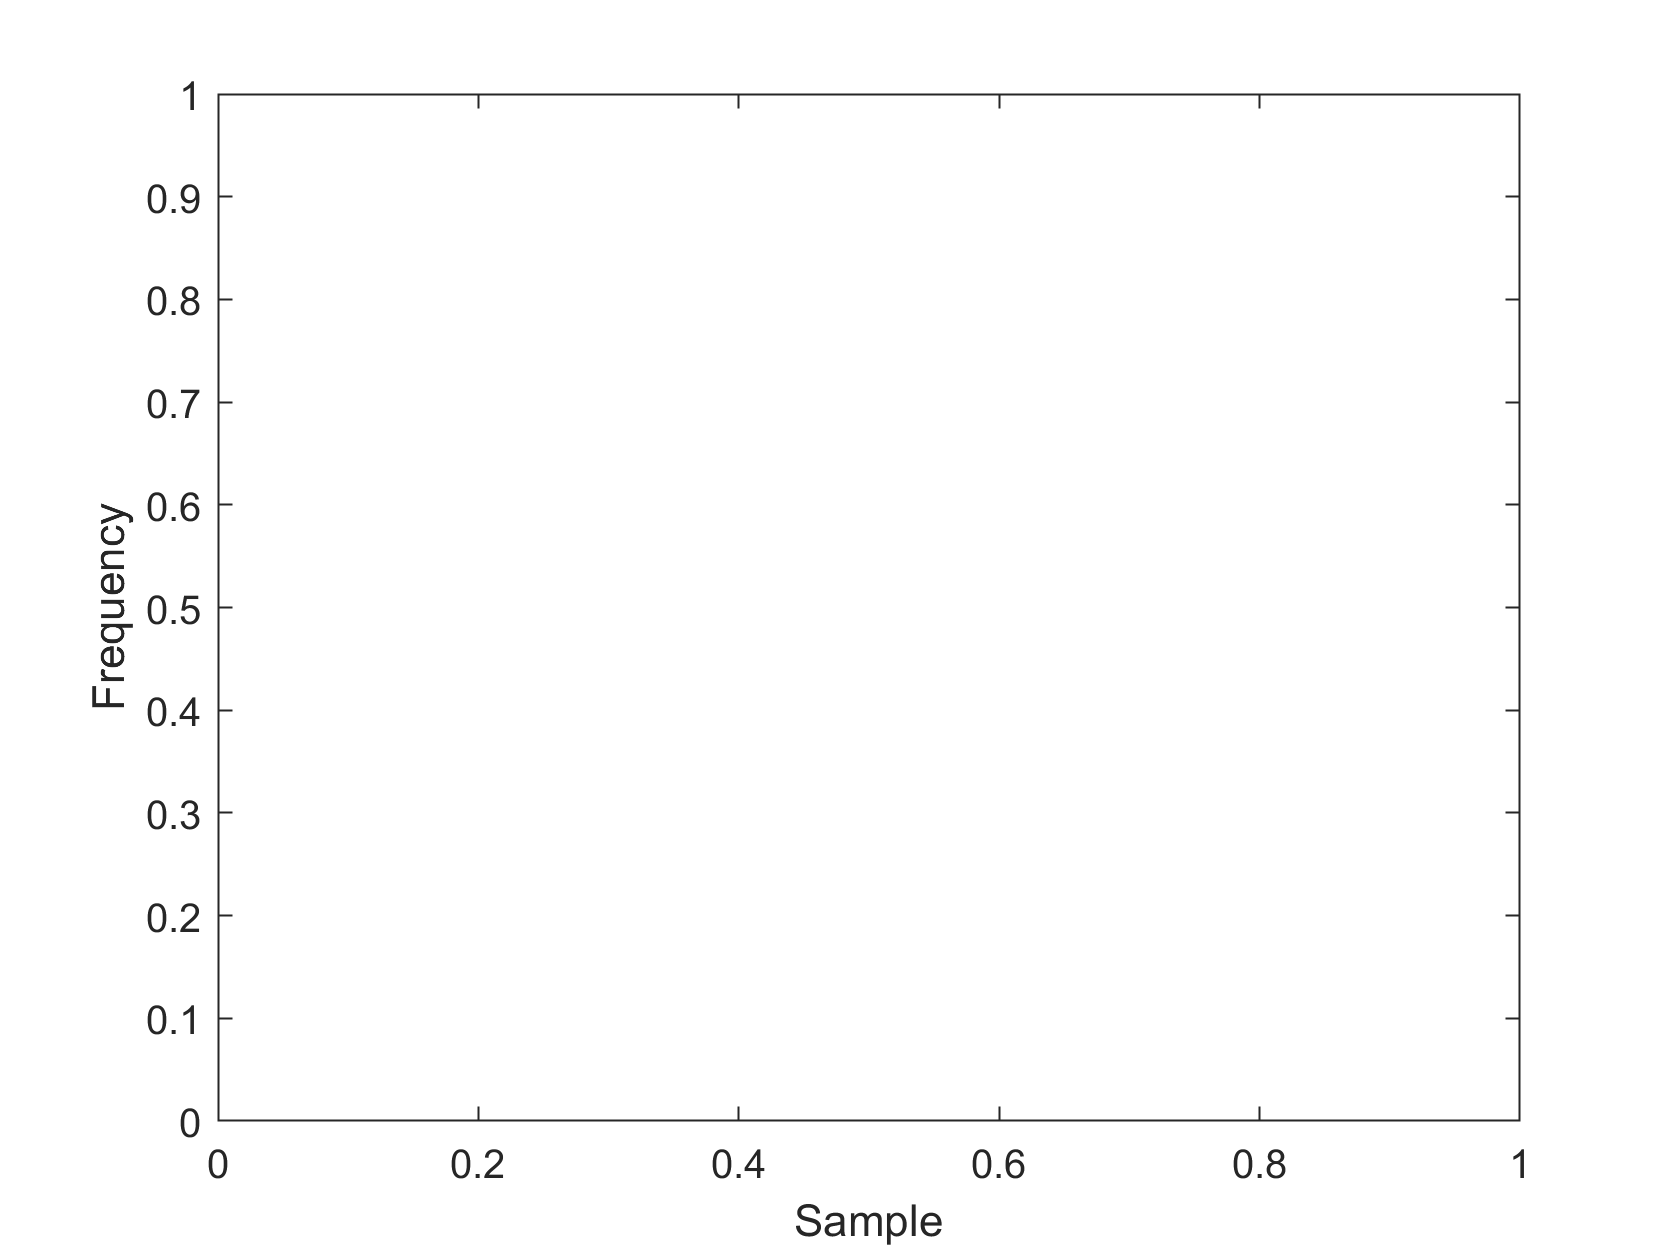

plot(k1);
ylabel('Frequency');
xlabel('Sample');

plot(k2);
ylabel('Frequency');
xlabel('Sample');

KMean function

function [DatMean, new_k1, new_k2, new_k3, new_k4, new_k5, new_k6, new_k7, new_k8] = KMeanFunction(NumTrainCase, DatMean, series_edit, k1, k2, k3, k4, k5, k6, k7, k8)
    new_k1 = zeros(1,397);
    new_k2 = zeros(1,397);
    new_k3 = zeros(1,397);
    new_k4 = zeros(1,397);
    new_k5 = zeros(1,397);
    new_k6 = zeros(1,397);
    new_k7 = zeros(1,397);
    new_k8 = zeros(1,397);
    k1_count = 0;
    k2_count = 0;
    k3_count = 0;
    k4_count = 0;
    k5_count = 0;
    k6_count = 0;
    k7_count = 0;
    k8_count = 0;

    for i=1:NumTrainCase
        k1_distance = 0;
        k2_distance = 0;
        k3_distance = 0;
        k4_distance = 0;
        k5_distance = 0;
        k6_distance = 0;
        k7_distance = 0;
        k8_distance = 0;
        for j=11:387
            k1_distance = k1_distance + abs(k1(1,j) - DatMean.Data(i,j+series_edit(i)));
            k2_distance = k2_distance + abs(k2(1,j) - DatMean.Data(i,j+series_edit(i)));
            k3_distance = k3_distance + abs(k3(1,j) - DatMean.Data(i,j+series_edit(i)));
            k4_distance = k4_distance + abs(k4(1,j) - DatMean.Data(i,j+series_edit(i)));
            k5_distance = k5_distance + abs(k5(1,j) - DatMean.Data(i,j+series_edit(i)));
            k6_distance = k6_distance + abs(k6(1,j) - DatMean.Data(i,j+series_edit(i)));
            k7_distance = k7_distance + abs(k7(1,j) - DatMean.Data(i,j+series_edit(i)));
            k8_distance = k8_distance + abs(k8(1,j) - DatMean.Data(i,j+series_edit(i)));
        end
        if ( ...
                k1_distance < k2_distance && ...
                k1_distance < k3_distance && ...
                k1_distance < k4_distance && ...
                k1_distance < k5_distance && ...
                k1_distance < k6_distance && ...
                k1_distance < k7_distance && ...
                k1_distance < k8_distance ...
                )
            k1_count = k1_count + 1;
            for k=11:387
                new_k1(1,k) = new_k1(1,k) + DatMean.Data(i,k+series_edit(i));
            end
            DatMean.kMean(i) = 1;
        elseif ( ...
                k2_distance < k1_distance && ...
                k2_distance < k3_distance && ...
                k2_distance < k4_distance && ...
                k2_distance < k5_distance && ...
                k2_distance < k6_distance && ...
                k2_distance < k7_distance && ...
                k2_distance < k8_distance ...
                )
            k2_count = k2_count + 1;
            for k=11:387
                new_k2(1,k) = new_k2(1,k) + DatMean.Data(i,k+series_edit(i));
            end
            DatMean.kMean(i) = 2;
        elseif ( ...
                k3_distance < k1_distance && ...
                k3_distance < k2_distance && ...
                k3_distance < k4_distance && ...
                k3_distance < k5_distance && ...
                k3_distance < k6_distance && ...
                k3_distance < k7_distance && ...
                k3_distance < k8_distance ...
                )
            k3_count = k3_count + 1;
            for k=11:387
                new_k3(1,k) = new_k3(1,k) + DatMean.Data(i,k+series_edit(i));
            end
            DatMean.kMean(i) = 3;
        elseif ( ...
                k4_distance < k1_distance && ...
                k4_distance < k2_distance && ...
                k4_distance < k3_distance && ...
                k4_distance < k5_distance && ...
                k4_distance < k6_distance && ...
                k4_distance < k7_distance && ...
                k4_distance < k8_distance ...
                )
            k4_count = k4_count + 1;
            for k=11:387
                new_k4(1,k) = new_k4(1,k) + DatMean.Data(i,k+series_edit(i));
            end
            DatMean.kMean(i) = 4;
        elseif ( ...
                k5_distance < k1_distance && ...
                k5_distance < k2_distance && ...
                k5_distance < k3_distance && ...
                k5_distance < k4_distance && ...
                k5_distance < k6_distance && ...
                k5_distance < k7_distance && ...
                k5_distance < k8_distance ...
                )
            k5_count = k5_count + 1;
            for k=11:387
                new_k5(1,k) = new_k5(1,k) + DatMean.Data(i,k+series_edit(i));
            end
            DatMean.kMean(i) = 5;
        elseif ( ...
                k6_distance < k1_distance && ...
                k6_distance < k2_distance && ...
                k6_distance < k3_distance && ...
                k6_distance < k4_distance && ...
                k6_distance < k5_distance && ...
                k6_distance < k7_distance && ...
                k6_distance < k8_distance ...
                )
            k6_count = k6_count + 1;
            for k=11:387
                new_k6(1,k) = new_k6(1,k) + DatMean.Data(i,k+series_edit(i));
            end
            DatMean.kMean(i) = 6;
        elseif ( ...
                k7_distance < k1_distance && ...
                k7_distance < k2_distance && ...
                k7_distance < k3_distance && ...
                k7_distance < k4_distance && ...
                k7_distance < k5_distance && ...
                k7_distance < k6_distance && ...
                k7_distance < k8_distance ...
                )
            k7_count = k7_count + 1;
            for k=11:387
                new_k7(1,k) = new_k7(1,k) + DatMean.Data(i,k+series_edit(i));
            end
            DatMean.kMean(i) = 7;
        elseif ( ...
                k8_distance < k1_distance && ...
                k8_distance < k2_distance && ...
                k8_distance < k3_distance && ...
                k8_distance < k4_distance && ...
                k8_distance < k5_distance && ...
                k8_distance < k6_distance && ...
                k8_distance < k7_distance ...
                )
            k8_count = k8_count + 1;
            for k=11:387
                new_k8(1,k) = new_k8(1,k) + DatMean.Data(i,k+series_edit(i));
            end
            DatMean.kMean(i) = 8;
        end
    end
    new_k1 = new_k1/k1_count;
    new_k2 = new_k2/k2_count;
    new_k3 = new_k3/k3_count;
    new_k4 = new_k4/k4_count;
    new_k5 = new_k5/k5_count;
    new_k6 = new_k6/k6_count;
    new_k7 = new_k7/k7_count;
    new_k8 = new_k8/k8_count;
end

Edit distance function

function [series_edit] = EditDistance(NumTrainCase, DatMean, series_average)
    series_edit = zeros(1,NumTrainCase);
    for i=1:NumTrainCase
        min_series_distance = 1000;
        for j=-10:10
            series_distance = 0;
            for k=11:387
                series_distance = series_distance + abs(series_average(1,k) - DatMean.Data(i,k+j));
            end
            if (series_distance < min_series_distance)
                min_series_distance = series_distance;
                series_edit(i) = j;
            end
        end
    end
end

 Average function

function [series_average] = Average(NumTrainCase, DatMean)
    series_average = zeros(1,397);
    for i=1:NumTrainCase
        for j=1:397
            series_average(j) = series_average(j) + DatMean.Data(i,j);
        end
    end
    series_average = series_average/NumTrainCase;
end
